# Test the Model

## Read in optimised hyperparameters

LSTMCNN

optVars = load("HyperParameterSearch\OptVars\LSTMCNNoptVars.mat").optVars;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
numLSTMBlocks = optVars.numLSTMBlocks;
numHiddenUnits = optVars.numHiddenUnits;
numCNNBlocks = optVars.numCNNBlocks;
filterSize = optVars.filterSize;
numFilters = optVars.numFilters;

biLSTM

optVars = load("HyperParameterSearch\OptVars\biLSTMoptVars.mat").optVars;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
numFeatures = 3;
numBlocks = optVars.numBlocks;
numHiddenUnits = optVars.numHiddenUnits;
numResponse = 3;

TCN

optVars = load("HyperParameterSearch\OptVars\TCNoptVars.mat").optVars;
numFilters = optVars.numFilters;
filterSize = optVars.filterSize;
numBlocks = optVars.numBlocks;
dropoutFactor = optVars.dropoutFactor;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;

CNN1d

optVars = load("HyperParameterSearch\OptVars\CNN1doptVars.mat").optVars;
numFilters = optVars.numFilters;
filterSize = optVars.filterSize;
numBlocks = optVars.numBlocks;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
poolSize = optVars.poolSize;

WTCNN

optVars = load("HyperParameterSearch\OptVars\WTCNNoptVars.mat").optVars;
imSize=size(imread('DataSet\HyperparameterSearch\Train\Img\WTImg\0001_wt.jpg'));
numBlocks = optVars.numBlocks;
filterSizeC= floor((optVars.filterSizeC)/2)*2+1;
filterSizeS= floor((optVars.filterSizeS)/2)*2+1;
numFilter= optVars.filterNum;
dropoutLayerRegularization = optVars.dropoutLayerRegularization;
learningrate = optVars.learningrate;
activation=optVars.activation;
miniBatchSize=optVars.batchSize;
classes = ["blink","noBlink", "muscleArtifact"];

## Test the model several times

rng(1);
numTesting = 10;
Maxepochs = 30;

LSTMCNN

modelName = 'LSTMCNN';
accuracy = {};
confusionmats = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    numResponse = numel(categories(YTest{1}));
    numFeatures = size(XTrain{1},1);
    layers = constructLSTMCNN(numFeatures,numLSTMBlocks,numHiddenUnits, ...
        numCNNBlocks,filterSize,numFilters,numResponse,false); 
    % train
    options = trainingOptions('adam', ...
        'MaxEpochs',Maxepochs, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    confusionmats{end+1} = confusionMat;
end

result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');

LSTM

modelName = 'LSTM';
accuracy = {};
confusionmats = {};
pred = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    layers = constructLSTM(numFeatures,numBlocks,numHiddenUnits,numResponse,false); 

    options = trainingOptions('adam', ...
        'MaxEpochs',30, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
        valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    pred{end+1} = YPred; 
    confusionmats{end+1} = confusionMat;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
end
result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');
save(['Test\Results\' modelName 'pred.mat'],'pred','-mat');

biLSTM

modelName = 'biLSTM';
accuracy = {};
confusionmats = {};
pred = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    layers = constructLSTM(numFeatures,numBlocks,numHiddenUnits,numResponse,false); 

    options = trainingOptions('adam', ...
        'MaxEpochs',30, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
        valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    pred{end+1} = YPred; 
    confusionmats{end+1} = confusionMat;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
end
result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');
save(['Test\Results\' modelName 'pred.mat'],'pred','-mat');

TCN

modelName = 'TCN';
accuracy = {};
confusionmats = {};
pred = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    layers = constructTCN(size(XTrain{1}, 1), numFilters, filterSize, numBlocks, dropoutFactor);

    options = trainingOptions('adam', ...
        'MaxEpochs',Maxepochs, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    
    
    net = trainNetwork(XTrain,YTrain,layers,options);

    
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
        valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    pred{end+1} = YPred; 
    confusionmats{end+1} = confusionMat;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
end
result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');
save(['Test\Results\' modelName 'pred.mat'],'pred','-mat');

1d-CNN

modelName = '1d-CNN';
accuracy = {};
confusionmats = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    numResponse = numel(categories(YTest{1}));
    numFeatures = size(XTrain{1},1);
    layers = constructCNN(size(XTrain{1}, 1), numBlocks, filterSize, numFilters,poolSize, 3);

        options = trainingOptions('adam', ...
            'MaxEpochs',Maxepochs, ...
            'MiniBatchSize',miniBatchSize, ...
            'InitialLearnRate',learningrate, ...
            'LearnRateDropPeriod',10, ...
            'LearnRateDropFactor',0.75, ...
            'LearnRateSchedule','piecewise', ...
            'Plots','none',...
            'GradientThreshold',1, ...
            'shuffle','every-epoch',...
            'Verbose',0,...
            'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    confusionmats{end+1} = confusionMat;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
end

result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');

WTCNN

     1

     2



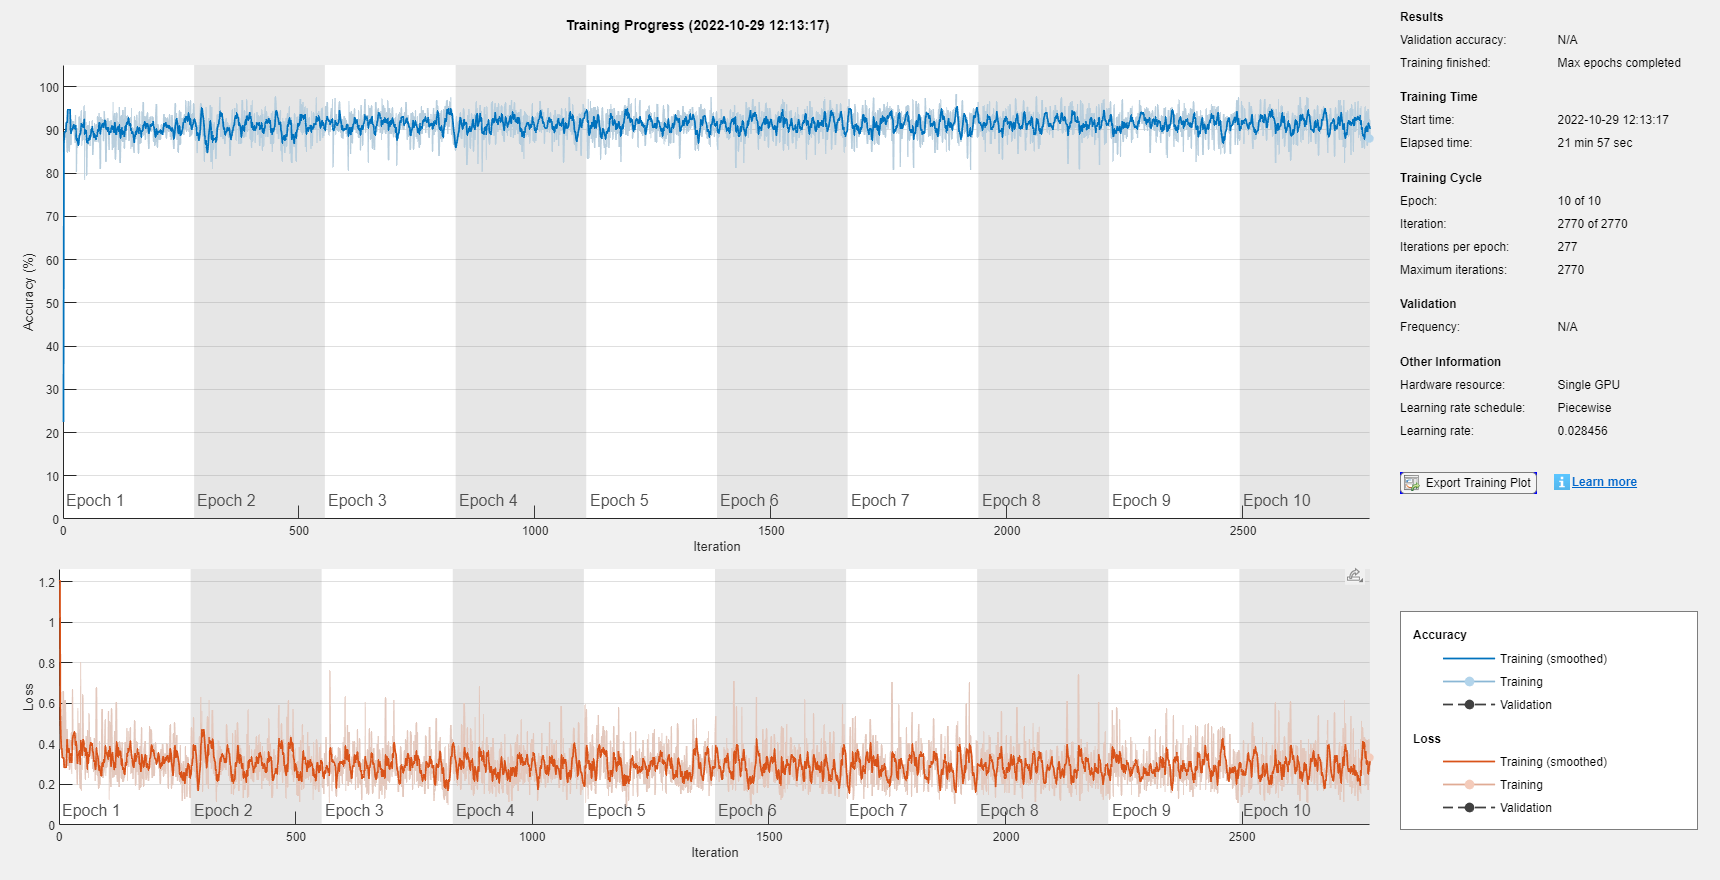

     3



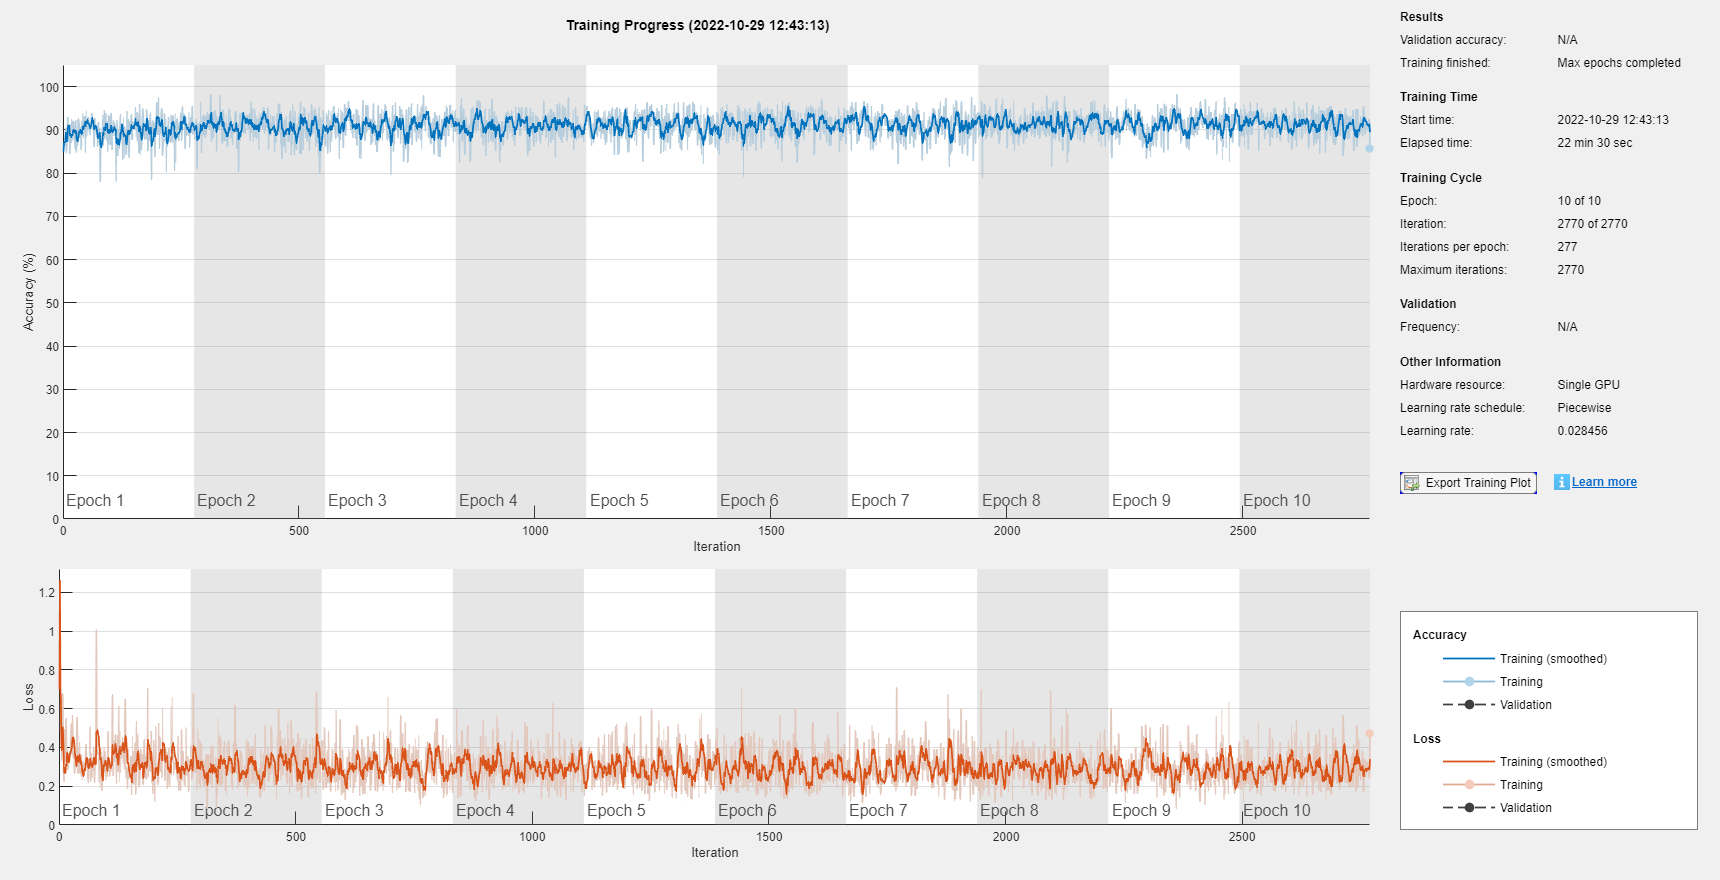

     4

     5

     6

     7

     8



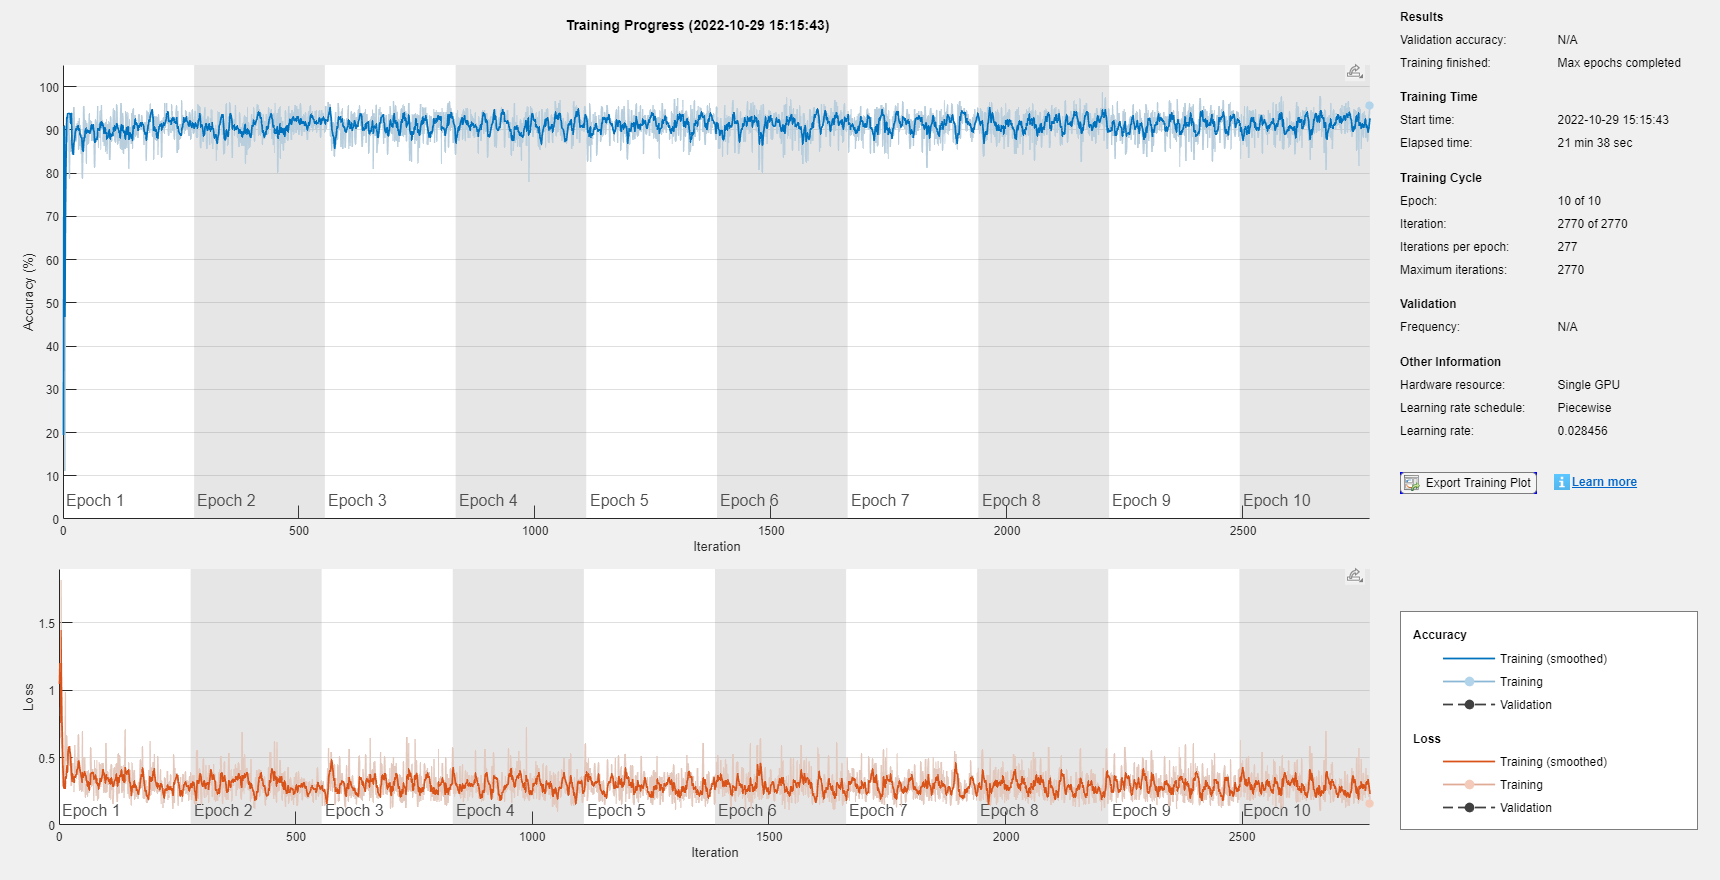

     9



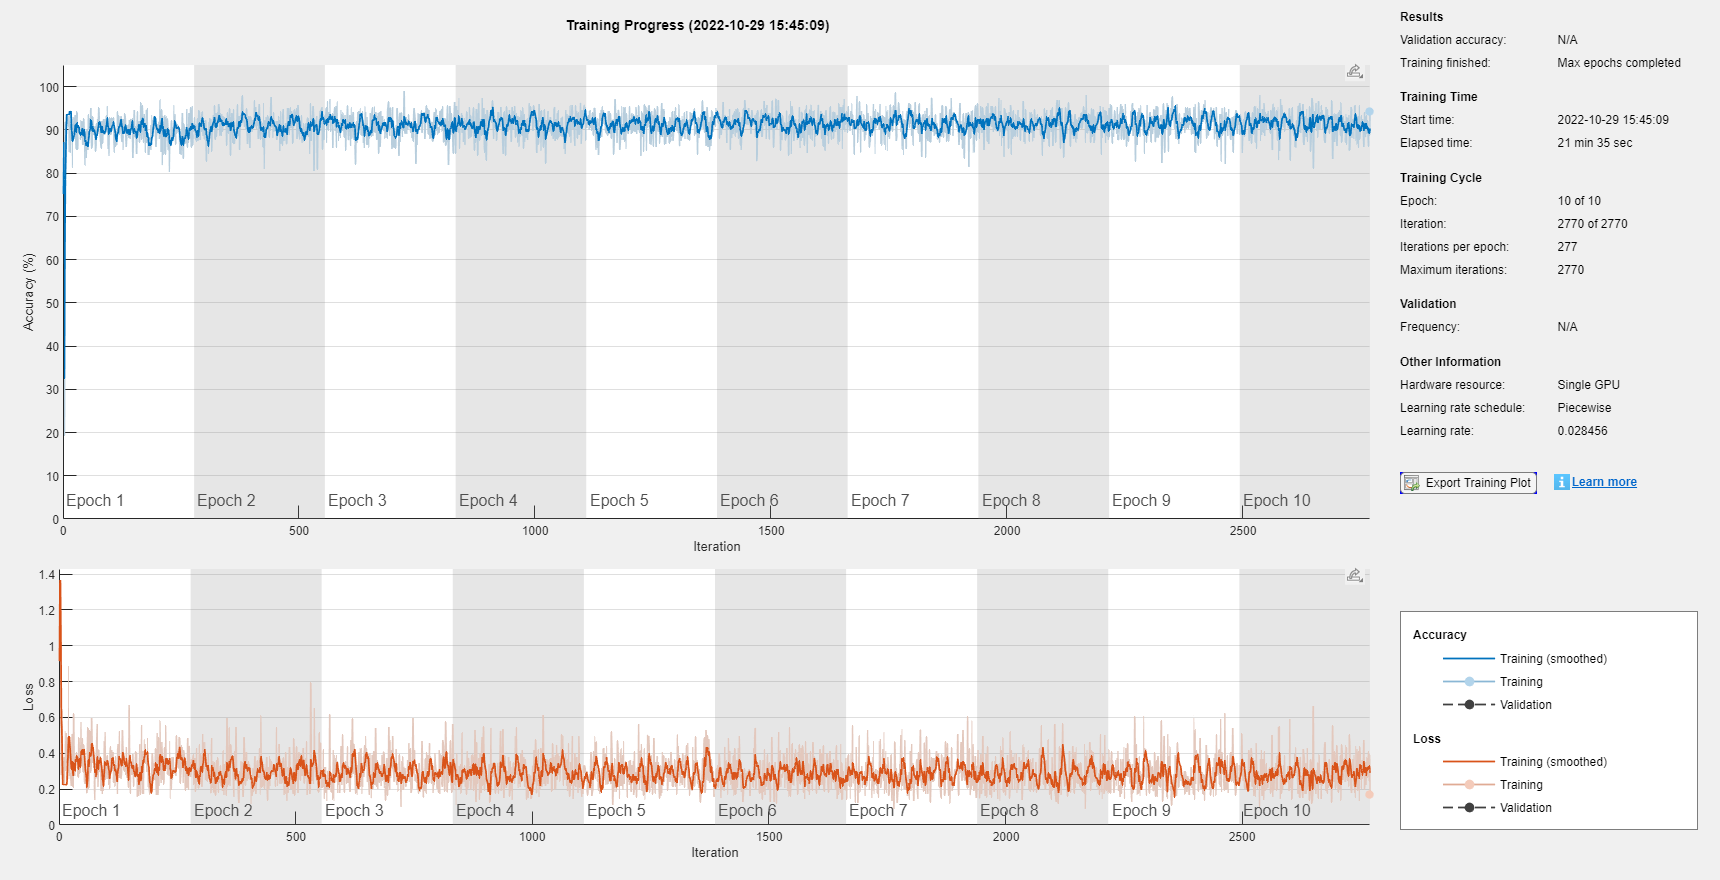

    10



modelName = 'WTCNN';
accuracy = {};
predResult = {};
learningrate = learningrate/3;
for i = 1:10%numTesting
    % load data set
    YLable = load(fullfile('DataSet','Test','Test',['YTestTest' num2str(i) '.mat'])).YTestTest;
    imdsTest = imageDatastore(fullfile('DataSet','Test','Test',['Img', num2str(i)],'WTImg'),FileExtensions=".jpg");
    testImgSize = [size(imread(imdsTest.Files{1,1})) 1 1];
    imgsTest = ones(testImgSize);
    for k =1:numel(imdsTest.Files)
        imgsTest = cat(4,imgsTest,reshape(imread(imdsTest.Files{k,1}), testImgSize));
    end
    imgsTest=imgsTest(:,:,:,2:end);
    
        % load data set
    YLable = load(fullfile('DataSet','Test','Test',['YTestTest' num2str(i) '.mat'])).YTestTest;
    TY = YLable{1};
    for k = 2:numel(YLable)
    TY = [TY;YLable{k}];
    end
    dsTest = {TY,imgsTest};

    YLable = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;
    dataClassNames = ["blink","n/a", "muscle-artifact"];pixelLabelIds = 1:numel(dataClassNames);
    classNames=["blink","noBlink", "muscleArtifact"];
    imdsTrain = imageDatastore(['DataSet\Test\Train\Img' num2str(i) '\WTImg'],FileExtensions=".jpg");
    pxdsTrain = pixelLabelDatastore(['DataSet\Test\Train\Img' num2str(i) '\PLImg'],classNames,pixelLabelIds);
    
    imdsTest = imageDatastore(['DataSet\Test\Test\Img' num2str(i) '\WTImg'],FileExtensions=".jpg");
    pxdsTest = pixelLabelDatastore(['DataSet\Test\Test\Img' num2str(i) '\PLImg'],classNames,pixelLabelIds);
    
    dsTrain = combine(imdsTrain,pxdsTrain);

    imSize=size(imread('DataSet\HyperparameterSearch\Train\Img\WTImg\0001_wt.jpg'));
    layers = simpleCNNpixel(imSize,numBlocks,filterSizeC,filterSizeS+4, ...
    numFilter, dropoutLayerRegularization,classes,activation); 
    % train
    options = trainingOptions('adam', ...
        'MaxEpochs',30, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(dsTrain,layers,options);
    % evaluate
    [YPred,scores,allScores]=semanticseg(imgsTest,net);
    valError = 1-mean(YPred == TY','all');
    accuracy{end+1} = valError;
    predResult{end+1} = YPred;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
    disp(i);

end


result = table(accuracy, predResult);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');

## Standard deviation of accuracy

modelName = 'WTCNN';
accuracyList = [];
accuracy = load(['Test\Results\' modelName 'result.mat']).result.accuracy;
for i = 1:numTesting
    accuracyList = [accuracyList, accuracy{i}];
end
accuracyMean = mean(accuracyList),accuracyStd = std(accuracyList)

accuracyMean = 0.9535

accuracyStd = 0.0071


figure;
confusionchart(load(['Test\Results\' modelName 'result.mat']).result.confusionmats{1}, ...
    {'blink' 'n/a' 'muscle-artifact'},'Normalization','column-normalized','RowSummary','row-normalized');

Error using indexing
Unrecognized table variable name 'confusionmats'.

## Blink detect accuracy

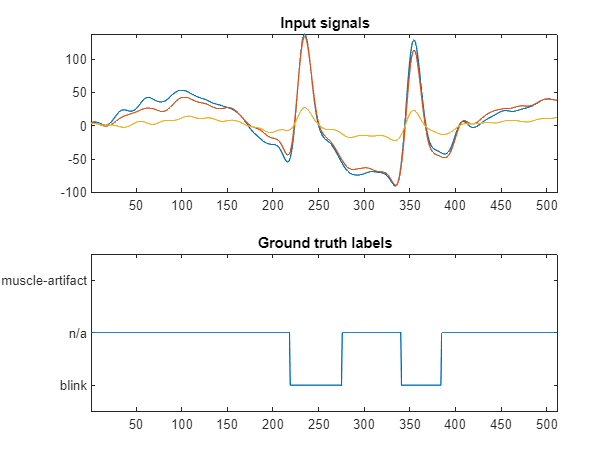

i = 1;
% i=errorList(2);
Ypred = YPred{i};
Ytest = YTest{i};
Xtest = XTest{i};
Xdif = diff(Xtest')';

figure;

subplot(2,1,1);plot(Xtest');xlim([1 512])
title("Input signals")

% subplot(4,1,2);plot(Xdif');xlim([1 512])
% title("Differential signals")

subplot(2,1,2);plot(Ytest);xlim([1 512])
title("Ground truth labels")


% subplot(4,1,4);plot(Ypred);xlim([1 512])
% title("Predict labels")

OC Pred

XTrain = load('DataSet\OpeningClosing\XTrain.mat').XTrain;
YTrain = load('DataSet\OpeningClosing\YTrain.mat').YTrain;
XTest = load('DataSet\OpeningClosing\XTest.mat').XTest;
YTest = load('DataSet\OpeningClosing\YTest.mat').YTest;
net = load('Models\trainedModels\TCNOCnet.mat').net;
YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
% blinkLocate(Xtest,Ytest),blinkLocate(Xtest,Ypred)YTest
valError = 0;
for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
end
accuracy = valError/length(YPred)

accuracy = 0.9412

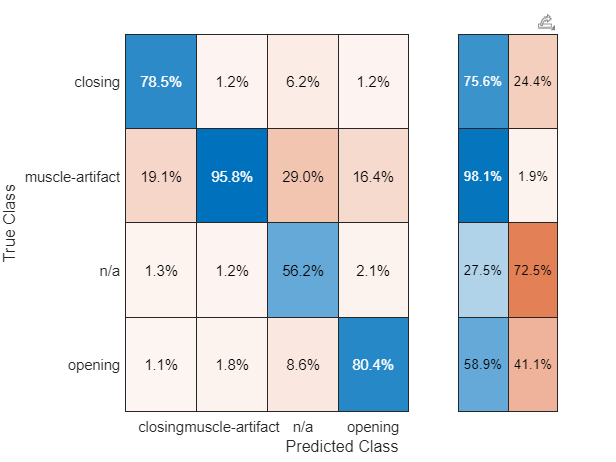

TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(YTest)
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end
confusionMat = confusionmat(TY(:),Y(:));
 confusionchart( confusionMat,...
    {'opening' 'closing' 'muscle-artifact' 'n/a'},'Normalization','column-normalized','RowSummary','row-normalized');

OC test

groundTruth = {};
predicted = {};
TP = 0;FP = 0;FN=0;
errorList = [];
for i = 1:numel(Ytest)
    gt = findBlinkFromOpeningClosing(YTest{i});
    p = findBlinkFromOpeningClosing(YPred{i});
    gt = gt{1};p=p{1};
    groundTruth{end+1} = gt;
    predicted{end+1} = p;
    
    TP = TP + numel(intersect(gt,p));
    if (numel(gt) > numel(p))
        FN = FN + numel(gt) - numel(p);
    else
        FP = FP + numel(p) - numel(gt);
    end
    if (numel(gt) ~= numel(p))
        errorList(end+1) = i;
    end        
end 
TP,FP,FN,errorList

TP = 240

FP = 20

FN = 10

errorList =      1    21    23    24    38    39    40    48    69    94    95    96   171   173   175   203   249   255   265   270   271   276   277   292   312   336   405   468


Precision=TP/(TP+FP),Recall=TP/(TP+FN)

Precision = 0.9231

Recall = 0.9600

only blink test


for i=1:10

    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest; 

groundTruth = {};
predicted = {};
TP = 0;FP = 0;FN=0;
errorList = [];
YPred = Pred{1};
YPred(YPred=='noBlink')='n/a';

for k = 1:numel(YTest)
    gt = blinkLocate(XTest{k},YTest{k});
    p = blinkLocate(XTest{k},YPred(:,k));
    groundTruth{end+1} = gt;
    predicted{end+1} = p;
    
    TP = TP + sum(ismembertol(gt,p,50));%numel(intersect(gt,p));
    if (numel(gt) > numel(p))
        FN = FN + numel(gt) - numel(p);
    else
        FP = FP + numel(p) - numel(gt);
    end
    if (numel(gt) ~= numel(p))
        errorList(end+1) = k;
    end        
end 
disp(i);
TP,FP,FN,errorList
Precision=TP/(TP+FP),Recall=TP/(TP+FN)
end

     1



TP = 1966

FP = 206

FN = 627

errorList =     36    46    69   108   167   168   198   221   229   249   257   260   261   262   276   280   281   287   288   289   290   291   292   311   314   317   318   319   320   321   322   323   324   325   326   327   328   331   332   333   334   338   339   365   405   412   449   520   527   528


Precision = 0.9052

Recall = 0.7582

     2



TP = 1595

FP = 455

FN = 1058

errorList =      3     4     5     7     8    10    13    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    40    41    42    43    44    45    46    48    49    50    53    54    55    57    58    59    60    61    63    66    67


Precision = 0.7780

Recall = 0.6012

     3



TP = 1595

FP = 477

FN = 1165

errorList =      2     4     5     6     8    11    12    13    15    17    20    21    22    24    25    26    29    30    31    32    33    34    35    36    38    40    41    43    44    46    47    48    49    50    53    55    56    57    59    60    61    63    64    67    68    69    79    80    81    82


Precision = 0.7698

Recall = 0.5779

     4



TP = 1650

FP = 412

FN = 1076

errorList =      1     2     3     4     5     8    10    11    12    13    14    16    17    18    19    24    25    26    27    28    31    34    35    36    38    39    40    41    42    43    44    46    50    51    53    54    55    56    57    58    62    65    66    67    69    94    95   100   101   102


Precision = 0.8002

Recall = 0.6053

     5



TP = 1619

FP = 455

FN = 1033

errorList =      1     2     3     4     5     6     8    11    12    13    15    16    17    19    20    23    24    25    27    28    29    30    34    35    36    37    38    39    40    41    43    44    45    47    48    50    52    55    57    58    60    61    62    63    64    67    68    69    95    96


Precision = 0.7806

Recall = 0.6105

     6



TP = 1603

FP = 479

FN = 1100

errorList =      1     2     3     4     5     7     8    10    13    15    17    18    21    22    23    24    25    27    29    30    31    32    33    34    35    36    37    38    39    42    43    44    46    47    49    50    51    53    55    56    57    58    60    61    63    64    66    67    68    69


Precision = 0.7699

Recall = 0.5930

     7



TP = 1618

FP = 456

FN = 1104

errorList =      2     3     4     5     8    10    11    12    13    16    19    20    22    23    24    26    27    29    30    31    32    33    34    35    36    37    38    39    40    42    43    46    48    49    50    51    52    55    56    57    58    59    61    63    64    66    67    68    69    95


Precision = 0.7801

Recall = 0.5944

     8



TP = 1589

FP = 475

FN = 1049

errorList =      1     2     3     4     5     7     8     9    10    11    12    13    17    18    23    24    25    26    27    28    29    30    32    34    35    36    37    38    39    45    48    51    53    54    55    58    59    60    61    63    64    67    68    69    88    89    90    91    92    93


Precision = 0.7699

Recall = 0.6024

     9



TP = 1630

FP = 454

FN = 1057

errorList =      2     3     4     6     7     8    10    11    12    14    15    16    17    18    20    21    22    23    24    25    26    27    28    29    36    39    40    41    44    46    48    49    50    51    54    55    56    57    58    60    61    63    64    66    67    68    69    85    86    87


Precision = 0.7821

Recall = 0.6066

    10



TP = 1572

FP = 467

FN = 1020

errorList =      2     4     5     6     8     9    10    11    12    13    18    20    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    42    43    44    45    46    47    49    50    51    52    53    55    56    57    58    59    60    61    63


Precision = 0.7710

Recall = 0.6065

for p = 0:5
tic;
i = 1;
[location,timePassed,mask] = detectBlinks(rawDs{1}.Variables',512,'1d-CNN',shiftFactor=p,plot=0,output={'location','time','mask'});
toc
end

Elapsed time is 8.711809 seconds.
Elapsed time is 10.020271 seconds.
Elapsed time is 10.610138 seconds.
Elapsed time is 11.000455 seconds.
Elapsed time is 13.678605 seconds.
Elapsed time is 17.697428 seconds.
